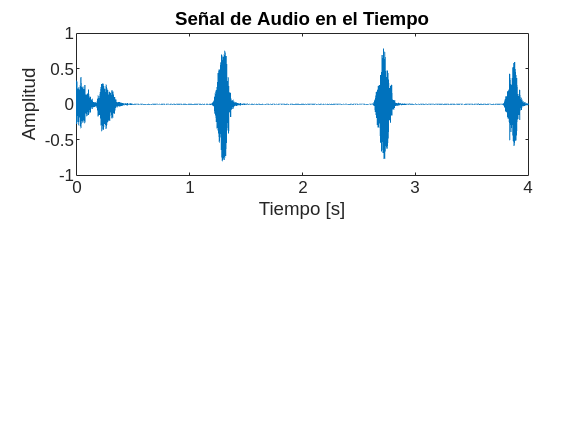

clc;
clear;

[audio, Fs] = audioread('perros3.wav'); 
N = length(audio);  % Número de muestras
t = (0:N-1)/Fs;  % Vector de tiempo para graficar la señal en segundos

%audio = audio;

% Figura para la señal en el tiempo
figure;
subplot(2,1,1); 
plot(t, audio);
title('Señal de Audio en el Tiempo');
xlabel('Tiempo [s]');
ylabel('Amplitud');

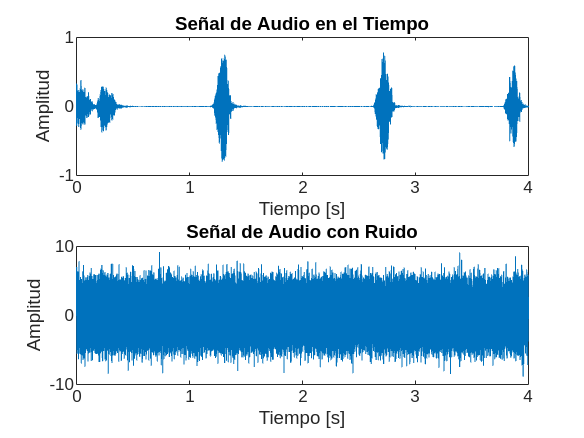

% Añadir ruido
X = 2*randn(size(audio)) + audio;
subplot(2,1,2); 
plot(t, X);
title('Señal de Audio con Ruido');
xlabel('Tiempo [s]');
ylabel('Amplitud');

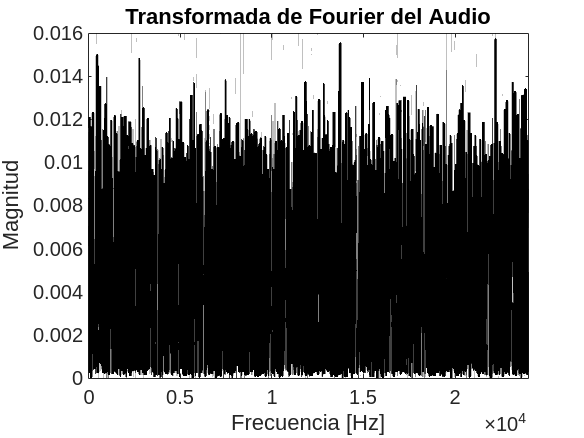

%Calcular la FFT
fourier = fft(X);  % Transformada de Fourier
frecuencias = (0:N-1)*(Fs/N); % Vector de frecuencias

% Figura para la FFT
figure;
plot(frecuencias, abs(fourier)/N, 'k', 'LineWidth', 1.5);
title('Transformada de Fourier del Audio');
xlabel('Frecuencia [Hz]');
ylabel('Magnitud');
xlim([0 Fs/2]); % Solo mostrar frecuencias hasta la mitad de Fs

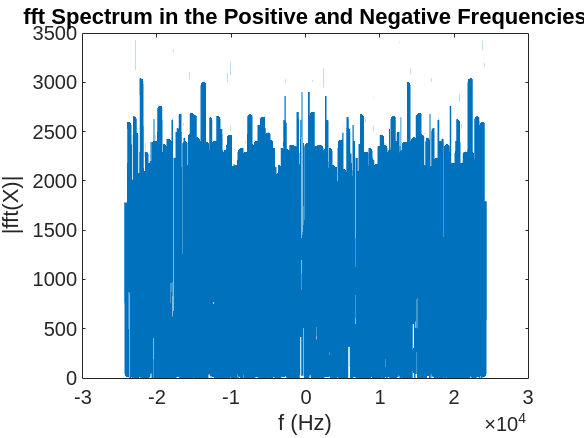

plot(Fs/N*(-N/2:N/2-1),abs(fftshift(fourier)),"LineWidth",3)
title("fft Spectrum in the Positive and Negative Frequencies")
xlabel("f (Hz)")
ylabel("|fft(X)|")

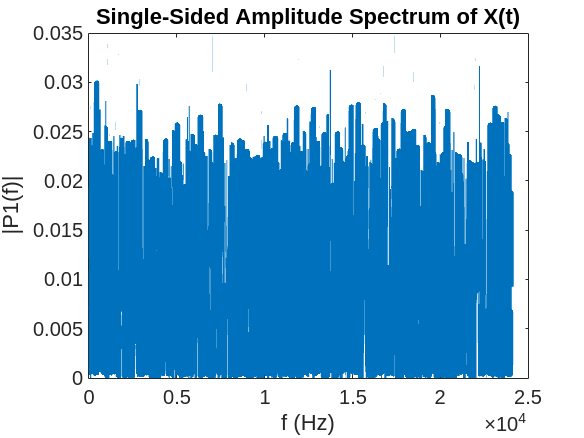


P2 = abs(fourier/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);


f = Fs/N*(0:(N/2));
plot(f,P1,"LineWidth",3) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")


fourier = fft(audio);
P2 = abs(fourier/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);

%plot(f,P1,"LineWidth",3) 
%title("Single-Sided Amplitude Spectrum of S(t)")
%xlabel("f (Hz)")
%ylabel("|P1(f)|")


% Encontrar la frecuencia fundamental
[magnitud_max, idx] = max(abs(fourier));  % Encuentra el pico máximo
frecuencia_fundamental = frecuencias(idx);  % Obtiene la frecuencia correspondiente

disp(['La frecuencia fundamental es: ', num2str(frecuencia_fundamental), ' Hz']);

La frecuencia fundamental es: 491 Hz
